This script is used to generate the figures used in the following manuscript:

%{
The following lines need to be excicuted before any figures are created
%}
%housekeeping
clc
clear
close all

% Use file drgCaImAn_LDAfsdz_choices_spm_noneg_Grin678and9_05242023
% below needs to be removed and replaced with NWB addresses
[choiceFileName,choiceBatchPathName] = uigetfile({'drgCaImAn_LDAfsdz_choices*.m'},'Select the .m file with all the choices for analysis');
addpath(choiceBatchPathName)

AllSessions = eval(choiceFileName(1:end-2));
AllSessions.choiceFileName=choiceFileName;
AllSessions.choiceBatchPathName=choiceBatchPathName;
% above will need to be replaced with NWB file locations
%
%loading each file and calculating the session's percent
%correct with a threshold of 80% for inclusion
AllSessions.percent_correct.value = nan(AllSessions.no_files,1);
AllSessions.percent_correct.include = nan(AllSessions.no_files,1);
startTime = tic;
for fileNo=1:length(AllSessions.FileName_pre_per)
    %
    PathName=AllSessions.PathName_pre_per{fileNo};
    FileName=AllSessions.FileName_pre_per{fileNo};
    %
    % remove below once NWB addresses are added
    if PathName(1:5) == "/data"
        PathName = append('R:/SFTP/Ming Ma/', PathName(12:end));
    end
    loadedVals = load([PathName FileName],'epochs','epoch_per_trial');
    epochs = loadedVals.epochs;
    epoch_per_trial = loadedVals.epoch_per_trial;
    trial_amt = size(epoch_per_trial,2);
    %determining the percent correct for a given session
    F= parfeval(@FindPercentCorrect,1,trial_amt,epochs);
    wait(F,"finished");
    AllSessions.percent_correct.value(fileNo) = F.OutputArguments{:,1};

    if AllSessions.percent_correct.value(fileNo) >= 80
        AllSessions.percent_correct.include(fileNo) = 1;
    else
        AllSessions.percent_correct.include(fileNo) = 0;
    end

end
FileAmt = fileNo;
disp(toc(startTime));

  279.1125



Figure 1.

%Using file Slide1.sld - 1-pwer21-Frame2-spm-042922_E_10_Iter_3500_output_ncorr_extract_batchv2_pre_per.mat
%Load file
[pre_perFileName,pre_perPathName] = uigetfile({'*pre_per.mat'},'Select the pre_per.mat file for analysis');
load([pre_perPathName pre_perFileName],'traces','time','handles','no_odor_trials','dt_before','acq_rate')


Figure 1.C

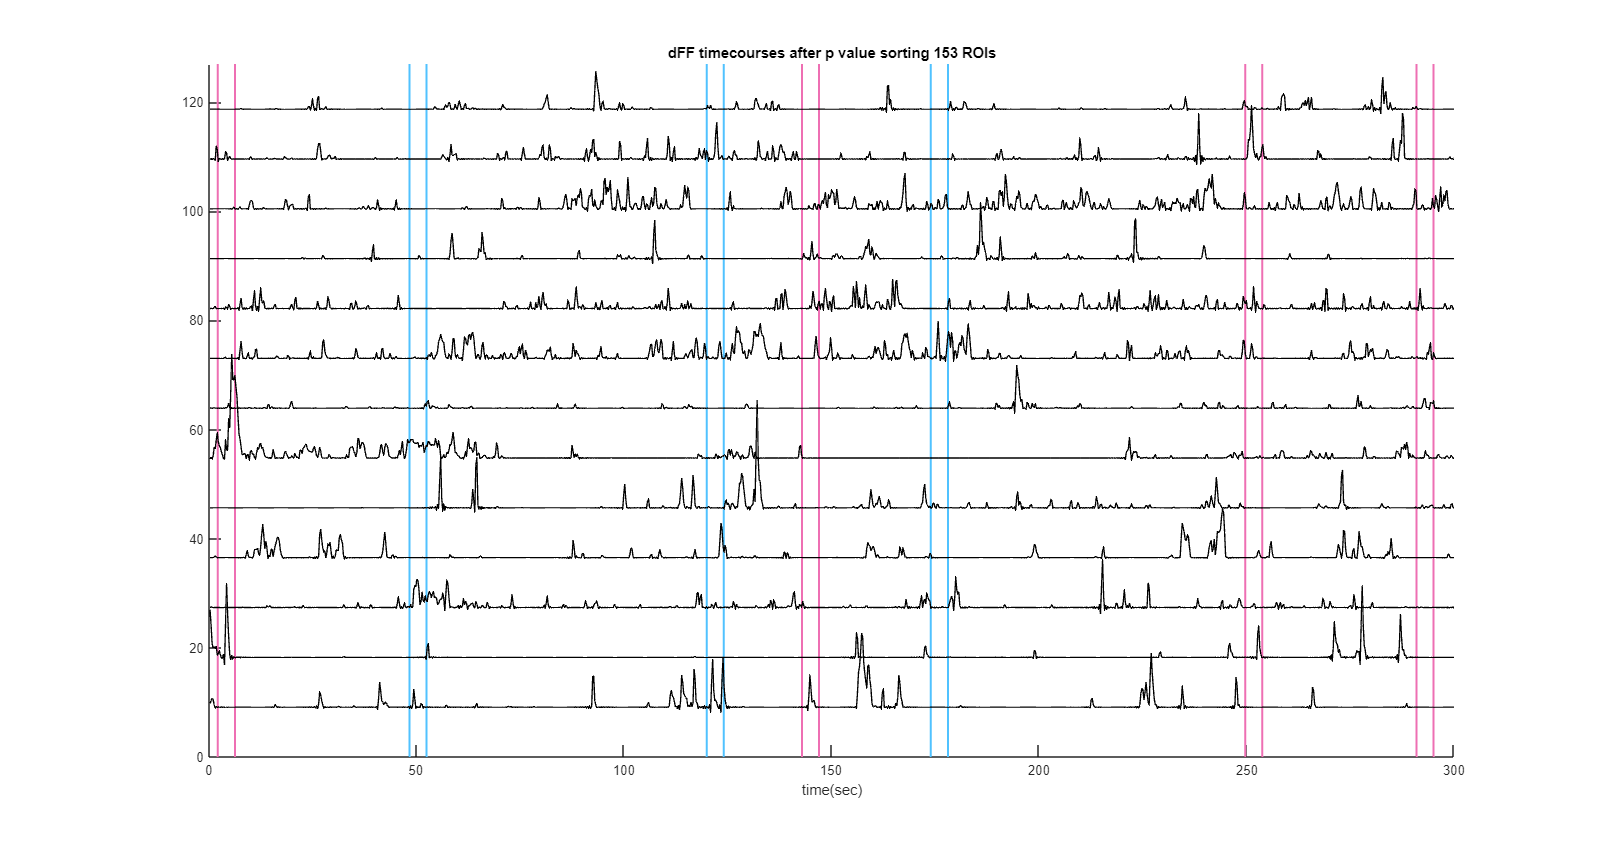

post_time=5; %The decoding model will be trained with all points in post_time sec interval starting post_shift secs after odor on
pre_time=5; %Used to calculate the decoding accuracy pre_time sec before post_shift
post_shift=0; %Set to 0 if you want to train with odor on points
dt_span=40; %Seconds shown before and after odor on in the figures
dt_p_threshold=4.2; %Time to be used after the odor on for the p_threshold t_test
%Post points
Nall=size(traces,1);
dt=median(time(2:end)-time(1:end-1));
ii_p_threshold=ceil(dt_p_threshold/dt);
no_points_post=floor(post_time/dt);
no_points_post_shift=floor(post_shift/dt);
no_points_pre=floor(pre_time/dt);
measurements_post=[];
measurements_pre=[];
epochs_sp_post=zeros(1,length(time));
epochs_sp_pre=zeros(1,length(time));
epochs_sm_post=zeros(1,length(time));
epochs_sm_pre=zeros(1,length(time));
which_model_for_traces_loo=no_odor_trials*ones(1,size(traces,2));

%Do both S+ and S-
at_end=0;
this_ii=0;
ii_post=0;
ii_pre=0;
ii=0;
trial_no=0;
ii_sp_post=0;
ii_sm_post=0;
ii_which_model=0;
dt_post_which_model=floor(20/dt); %Points that model will be used beyond the training period
ii_span=ceil(dt_span/dt);
dFF_per_trial_sp=[];
dFF_per_trial_sm=[];
dFFs_sp_per_trial_per_ROI=[];
dFFs_sm_per_trial_per_ROI=[];
hit_per_trial=[];
miss_per_trial=[];
cr_per_trial=[];
fa_per_trial=[];

for trace_no=1:size(traces,1)
    traces(trace_no,:)=traces(trace_no,:)/std(traces(trace_no,:));
end
[hit_per_trial,cr_per_trial,dFFs_sp_per_trial_per_ROI,...
    dFFs_sm_per_trial_per_ROI,dFF_per_trial_sm,dFF_per_trial_sp,training_decisions_post,...
    which_model_for_traces_loo,decisions_per_trial,...
    ii_pointer_to_td,epochs_sp_post,measurements_post,...
    measurements_pre,epochs_sp_pre,ii_post,trial_no...
    ,epochs_sm_post,epochs_sm_pre,miss_per_trial,fa_per_trial] = ...
    drgCaImAn_parse_out_trials(dt, dt_span,epochs,no_points_post_shift,no_points_post,no_points_pre,traces,ii_p_threshold,no_odor_trials);

% Determine the y spacing of the traces
y_shift=6*(prctile(traces(:),95)-prctile(traces(:),5));

FigOneC = figure();

hold("on")
set(FigOneC, 'units','normalized','position',[.05 .1 .85 .8])
p_values=ones(1,size(dFFs_sm_per_trial_per_ROI,2));
for iiROI=1:size(dFFs_sm_per_trial_per_ROI,2)
    dFF_sm=zeros(size(dFFs_sm_per_trial_per_ROI,1),size(dFFs_sm_per_trial_per_ROI,3));
    dFF_sm(:,:)=dFFs_sm_per_trial_per_ROI(:,iiROI,:);
    dFF_sp=zeros(size(dFFs_sp_per_trial_per_ROI,1),size(dFFs_sp_per_trial_per_ROI,3));
    dFF_sp(:,:)=dFFs_sp_per_trial_per_ROI(:,iiROI,:);

    [h,p_values(iiROI)]=ttest2(mean(dFF_sp,2),mean(dFF_sm,2));
end
no_traces=size(traces,1);
%Plot the trimmed traces sorted according to p values
to_sort=zeros(no_traces,2);
to_sort(:,1)=1:no_traces;
to_sort(:,2)=p_values;
sorted=sortrows(to_sort,2);
traces_sorted=zeros(no_traces,1);
traces_sorted(:,1)=sorted(:,1);
 %Plot the traces and do z normalization
%For S+ and S- plot odor on and reinforcement
for epoch=1:handles.dropcData.epochIndex
    %Epoch 2 is odor on, 3 is odor off
    plot_epoch=(handles.dropcData.epochEvent(epoch)==2)||(handles.dropcData.epochEvent(epoch)==3);
    if plot_epoch
        if handles.dropcData.epochTypeOfOdor(epoch)==handles.dropcProg.splusOdor
            plot([handles.dropcData.epochTime(epoch) handles.dropcData.epochTime(epoch)], [0 (no_traces+2)*y_shift],...
                'Color',[80/255 194/255 255/255],'LineWidth',1.5)
        else
            plot([handles.dropcData.epochTime(epoch) handles.dropcData.epochTime(epoch)], [0 (no_traces+2)*y_shift],...
                'Color',[238/255 111/255 179/255],'LineWidth',1.5)
        end
    end
end


for trNo=1:no_traces
    % for trNo=1:20
    plot(decimate(time,5),decimate(traces(traces_sorted(trNo),:),5)+y_shift*trNo,'-k','LineWidth',1)
end

%         ylim([-y_shift*0.2 (no_traces+2)*y_shift])
xlim([0 300])
ylim([0 127])
xlabel('time(sec)')
title(['dFF timecourses after p value sorting ' num2str(size(measurements_post,2)) ' ROIs'])

Figure 1 D

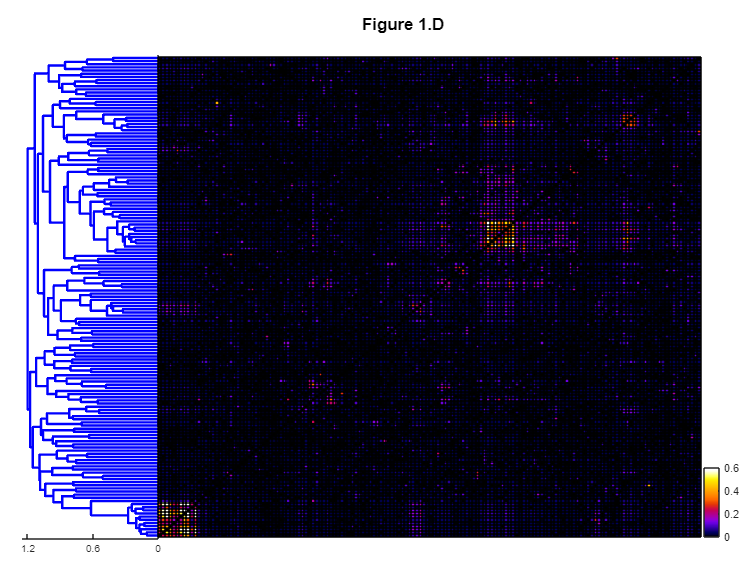

%{
The following will generate Figure 1.D
%}
FigOne = figure();
FigOne.Position(1) = FigOne.Position(1) + 500;
FigOne.Position(2) = FigOne.Position(2) + 400;
FigOne.Position(3) = FigOne.Position(3) + 500;
FigOne.Position(4) = FigOne.Position(4) + 400;

subplot(2,2,1:2)
text(.4,.5,'Figure 1.D','FontSize',14,'FontWeight','bold'); axis off
ax = gca;
ax.Position(1) = ax.Position(1) + 0.05;
ax.Position(2) = ax.Position(2) + 0.28;
ax.Position(4) = ax.Position(4) - 0.15;

for trace_nom=1:size(traces,1)
    traces(trace_nom,:)=traces(trace_nom,:)/std(traces(trace_nom,:));
end

%Calculate the crosscorrelations
croscorr_traces=abs(corrcoef(traces')); %please note that I am using the absolute value

%Set autocorrelations to zero
for ii=1:size(croscorr_traces,1)
    croscorr_traces(ii,ii)=0;
end
Z = linkage(croscorr_traces,'complete','correlation');
subplot(2,2,3)
ax = gca;
ax.Position(1) = ax.Position(1) - .1;
ax.Position(2) = ax.Position(2) - .053;
ax.Position(3) = ax.Position(3) - .15;
ax.Position(4) = ax.Position(4) + .505;
[H,T,outperm]=dendrogram(Z,0,'Orientation','left');
set(H,'LineWidth',2)
yticks([])
xticks([0 0.6 1.2])
xlim([0 1.25])

for ii=1:size(croscorr_traces,1)
    for jj=1:size(croscorr_traces,1)
        perm_croscorr_traces(ii,jj)=croscorr_traces(outperm(ii),outperm(jj));
    end
end

subplot(2,2,4)
ax = gca;
ax.Position(1) = ax.Position(1) - .356;
ax.Position(2) = ax.Position(2) - .05;
ax.Position(3) = ax.Position(3) + .40;
ax.Position(4) = ax.Position(4) + .5;
hold on
pcolor(perm_croscorr_traces)
colormap fire
clim([0 0.6])
ylim([1 153])
yticks([])
xlim([1 153])
xticks([])

cbOne = colorbar(ax,"eastoutside");
cbOne.Position(1) = cbOne.Position(1) + .05;
cbOne.Position(4) = cbOne.Position(4) - .72;

Figure 1.E

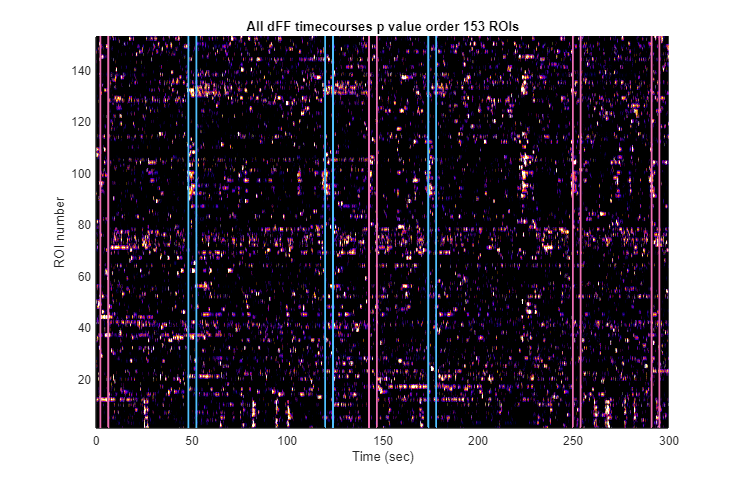

FigOneE = figure();
FigOneE.Position(1) = FigOneE.Position(1) + 700;
FigOneE.Position(2) = FigOneE.Position(2) + 400;
FigOneE.Position(3) = FigOneE.Position(3) + 700;
FigOneE.Position(4) = FigOneE.Position(4) + 400;
y_shift=6*(prctile(traces(:),95)-prctile(traces(:),5));
no_traces=size(traces,1);
hier_traces=zeros(size(traces,1),size(traces,2));

for trNo=1:no_traces
    hier_traces(trNo,:)=traces(outperm(trNo),:);
end

drg_pcolor(repmat(time',1,no_traces),repmat([1:no_traces],length(time),1),hier_traces')



colormap fire
shading interp
cmax=prctile(traces(:),99);
cmin=prctile(traces(:),1);
clim([cmin cmax]);

hold on
%Plot the traces and do z normalization
%For S+ and S- plot odor on and reinforcement
for epoch=1:handles.dropcData.epochIndex
    %Epoch 2 is odor on, 3 is odor off
    plot_epoch=(handles.dropcData.epochEvent(epoch)==2)||(handles.dropcData.epochEvent(epoch)==3);
    if plot_epoch
        if handles.dropcData.epochTypeOfOdor(epoch)==handles.dropcProg.splusOdor
            plot([handles.dropcData.epochTime(epoch) handles.dropcData.epochTime(epoch)], [0 (no_traces+2)*y_shift],...
                'Color',[80/255 194/255 255/255],'LineWidth',1.5)
        else
            plot([handles.dropcData.epochTime(epoch) handles.dropcData.epochTime(epoch)], [0 (no_traces+2)*y_shift],...
                'Color',[238/255 111/255 179/255],'LineWidth',1.5)
        end
    end
end


xlabel('Time (sec)')
ylabel('ROI number');
ylim([1 no_traces])
xlim([0 300])
title(['All dFF timecourses p value order ' num2str(size(traces,1)) ' ROIs'])

Figure 2.

Figure 3.

Figure 5. 

%separate the clusters according to diversion times
%setting constant values


%
cluster_times=[-1.5 -1;-1 0; 0 1; 1 2; 2 3; 3 200];
cluster_labels{1}='-1.5 to -1 sec';
cluster_labels{2}='-1 to 0 sec';
cluster_labels{3}='0 to 1 sec';
cluster_labels{4}='1-2 sec';
cluster_labels{5}='2-3 sec';
cluster_labels{6}='>3sec';



% Time events of interest (e.g. stimulus onset/offset, cues etc.)
% They are marked on the plots with vertical lines
delta_odor=4.127634e+00;
delta_odor_on_reinf_on=4.415787e+00;
delta_reinf=4.078266e-01;
timeEvents = [-1.5 0 delta_odor delta_odor_on_reinf_on delta_reinf+delta_odor_on_reinf_on];

amtRun = 0;
includeNum = 1;
startingTime = tic;
for Snum = 1:FileAmt
    if AllSessions.percent_correct.include(Snum) == 1
        amtRun = amtRun +1;
        %Do only for proficient
        FileName = AllSessions.FileName_pre_per{:,Snum};
        PathName = AllSessions.PathName_pre_per{:,Snum};
        for ii_ROI_choices=1:length(all_no_ROIs)
            %
            % below needs to be removed once NWB files are used
            
            FigEight_choices.show_figures=0;
            FigEight_choices.pre_perFileName = [FileName(1:end-4) '_rdec.mat'];
            FigEight_choices.pre_perPathName = PathName;
            % above needs to be edited once NWB is used
            %
            FigEight_choices.ii_out=ii_ROI_choices;
            FigEight_choices.time_windows=[3.1 4.1];
            FigEight_choices.time_windows_pre=[-1 0];
            FigEight_choices.time_window_lat=[-1.5 10];
            FigEight_choices.pre_time_window=[-7 -1.5];
            FigEight_choices.acc_thr=[0.35 0.65];
            FigEight_choices.dt_span=15;
            FigEight_choices.MLalgo=6;
            
            FigureEight.session(includeNum).fig8_ROI(ii_ROI_choices).decoding_output = decoding_Multi_ROI(FigEight_choices);
    
        end
        includeNum=includeNum+1;
    end
end
disp(toc(startingTime))

  857.9869



Figure 5.A-C

Figure 5.D-F

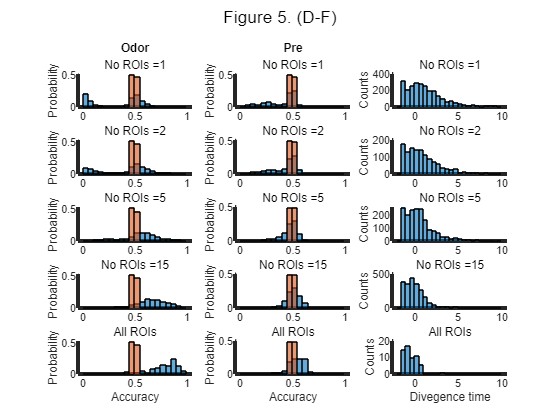

%{
Figure 8.D-F
A. Histogram for stimulus decoding accuracy calculated in the odor period (3.1 to 4.1 sec) for all proficient sessions (66 sessions) 
for 4 mice. i to v show the histogram for an increasing number of ROIs per decoding session. Blue is stimulus decoding accuracy, 
brown is stimulus decoding accuracy calculated after shuffling the labels. Histograms were normalized by dividing by the total 
number of counts.
B. Histograms calculated in the Pre period (-1 to 0 sec)
C. 
%}
%
%Plot accurcy histograms and do glm
glm_acc=[];
glm_acc_ii=0;
input_acc_data=[];
id_acc_ii=0;
%{
Setting constant values
%}
all_no_ROIs=[1 2 5 15 2000];
edges= 0:0.05:1;
loca_A = [1,4,7,10,13];
includeNum = 70;
epoch_labels{1}='Pre';
epoch_labels{2}='Odor';

figure();

for ii_ROI_choices=1:length(all_no_ROIs)

    subplot(length(all_no_ROIs),3,loca_A(ii_ROI_choices))
    ax=gca;
    ax.LineWidth=3;
    hold on

    all_accs=[];
    all_accs_sh=[];
    for fileNo=1:includeNum-1
        this_time_span=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.time_span;
        these_accs=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.accuracy_per_ROI;
        these_accs_sh=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.accuracy_per_ROI_sh;

        vetted_accs=[];
        ii_v=0;
        for ii_repeats=1:length(these_accs)
            this_acc_time_course=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy;
            %NOte: some of the noisy traces yield artifactual
            %accuracy above 0.5

            if mean(this_acc_time_course(this_time_span<-2))<0.53
                ii_v=ii_v+1;
                vetted_accs(ii_v)=these_accs(ii_repeats);
                vetted_accs_sh(ii_v)=these_accs_sh(ii_repeats);
            end
        end
        if ~isempty(vetted_accs)
            all_accs=[all_accs vetted_accs];
            all_accs_sh=[all_accs_sh vetted_accs_sh];

            glm_acc.data(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=vetted_accs;
            glm_acc.ROI_group(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=ii_ROI_choices*ones(1,length(vetted_accs));
            glm_acc.epoch(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=0*ones(1,length(vetted_accs));
            glm_acc_ii=glm_acc_ii+length(vetted_accs);

            id_acc_ii=id_acc_ii+1;
            input_acc_data(id_acc_ii).data=vetted_accs;
            if ii_ROI_choices<length(all_no_ROIs)
                input_acc_data(id_acc_ii).description=[epoch_labels{1} ' ' num2str(all_no_ROIs(ii_ROI_choices)) ' ROIs'];
            else
                input_acc_data(id_acc_ii).description=[epoch_labels{1} ' all ROIs'];
            end
        end

    end

    histogram(all_accs,edges,'Normalization','Probability')
    histogram(all_accs_sh,edges,'Normalization','Probability')

    if ii_ROI_choices~=length(all_no_ROIs)
        if ii_ROI_choices == 1
            title('Odor')
        end
        subtitle(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Accuracy')
    end
    ylabel('Probability')
    hold("off")
end

%Fig. 8B
edges=[0:0.05:1];
loca_B = [2,5,8,11,14];
for ii_ROI_choices=1:length(all_no_ROIs)
    subplot(length(all_no_ROIs),3,loca_B(ii_ROI_choices))
    ax=gca;ax.LineWidth=3;
    hold on
    all_accs=[];
    all_accs_sh=[];
    for fileNo=1:includeNum-1

        this_time_span=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.time_span;
        these_accs=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.accuracy_per_ROI_pre;
        these_accs_sh=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.accuracy_per_ROI_sh_pre;

        vetted_accs=[];
        ii_v=0;
        for ii_repeats=1:length(these_accs)
            this_acc_time_course=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy;
            %NOte: some of the noisy traces yield artifactual
            %accuracy above 0.5

            if mean(this_acc_time_course(this_time_span<-2))<0.53
                ii_v=ii_v+1;
                vetted_accs(ii_v)=these_accs(ii_repeats);
                vetted_accs_sh(ii_v)=these_accs_sh(ii_repeats);
            end
        end
        if ~isempty(vetted_accs)
            all_accs=[all_accs vetted_accs];
            all_accs_sh=[all_accs_sh vetted_accs_sh];

            if ~isempty(vetted_accs)
                all_accs=[all_accs vetted_accs];
                all_accs_sh=[all_accs_sh vetted_accs_sh];

                glm_acc.data(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=vetted_accs;
                glm_acc.ROI_group(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=ii_ROI_choices*ones(1,length(vetted_accs));
                glm_acc.epoch(glm_acc_ii+1:glm_acc_ii+length(vetted_accs))=1*ones(1,length(vetted_accs));
                glm_acc_ii=glm_acc_ii+length(vetted_accs);

                id_acc_ii=id_acc_ii+1;
                input_acc_data(id_acc_ii).data=vetted_accs;
                  if ii_ROI_choices<length(all_no_ROIs)
                    input_acc_data(id_acc_ii).description=[epoch_labels{2} ' ' num2str(all_no_ROIs(ii_ROI_choices)) ' ROIs'];
                else
                    input_acc_data(id_acc_ii).description=[epoch_labels{2} ' all ROIs'];
                end
            end
        end

    end
    histogram(all_accs,edges,'Normalization','Probability')
    histogram(all_accs_sh,edges,'Normalization','Probability')

    if ii_ROI_choices~=length(all_no_ROIs)
        if ii_ROI_choices == 1
            title('Pre')
        end
        subtitle(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Accuracy')
    end
    ylabel('Probability')
    hold("off")
end
%Fig. 8C
glm_lat=[];
glm_lat_ii=0;
input_lat_data=[];
id_lat_ii=0;
edges= -2:0.5:10 ;
loca_B = [3,6,9,12,15];
all_lats_per_ROI_choice=[];
for ii_ROI_choices=1:length(all_no_ROIs)
    subplot(length(all_no_ROIs),3,loca_B(ii_ROI_choices))
    ax=gca;ax.LineWidth=3;
    hold on

    all_lats=[];
    for fileNo=1:includeNum-1
        these_lats=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.latency_per_ROI;
        this_time_span=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.time_span;
        vetted_lats=[];
        ii_v=0;
        for ii_repeats=1:length(these_lats)
            this_acc_time_course=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy;
            %NOte: some of the noisy traces yield artifactual
            %accuracy above 0.5
            if (mean(this_acc_time_course(this_time_span<-2))<0.53)&(~isnan(these_lats(ii_repeats)))
                ii_v=ii_v+1;
                vetted_lats(ii_v)=these_lats(ii_repeats);
            end
        end
        if ~isempty(vetted_lats)
            all_lats=[all_lats vetted_lats];


            glm_lat.data(glm_lat_ii+1:glm_lat_ii+length(vetted_lats))=vetted_lats;
            glm_lat.ROI_group(glm_lat_ii+1:glm_lat_ii+length(vetted_lats))=ii_ROI_choices*ones(1,length(vetted_lats));
            % glm_lat.epoch(glm_lat_ii+1:glm_lat_ii+length(vetted_lats))=0*ones(1,length(vetted_lats));
            glm_lat_ii=glm_lat_ii+length(vetted_lats);

            id_lat_ii=id_lat_ii+1;
            input_lat_data(id_lat_ii).data=vetted_lats;
            if ii_ROI_choices<length(all_no_ROIs)
                input_lat_data(id_lat_ii).description=[num2str(all_no_ROIs(ii_ROI_choices)) ' ROIs'];
            else
                input_lat_data(id_lat_ii).description= 'all ROIs' ;
            end

        end
    end
  
    histogram(all_lats,edges)


    if ii_ROI_choices~=length(all_no_ROIs)
        subtitle(['No ROIs =', num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Divegence time')
    end
    ylabel('Counts')
    hold("off")
end

sgtitle('Figure 5. (D-F)')
hold off

Figure 5.G

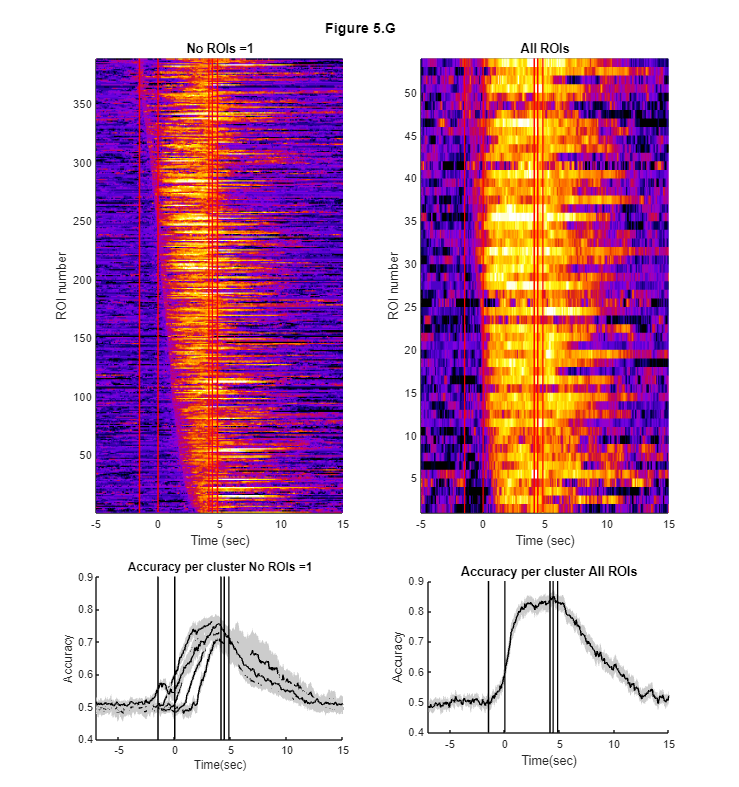

%{
Figure 8.D
(i). Time courses for decoding accuracies calculated with one ROI per session that reach at least 0.65 after 
trial start. 
(ii) Mean accuracy time courses calculated for one ROI accuracy time courses shown in Di with 
accuracy increase onsets in the following time windows: -1.5 to -1, -1 to 0, 0 to 1, 1 to 2, 2 to 3, >3 sec. 
(iii) Time courses for decoding accuracies calculated all ROIs per session. 
(iv) Mean accuracy time course for the time courses shown in Diii
%}
hFig = figure();
hFig.Position(1) = hFig.Position(1) + 350;
hFig.Position(2) = hFig.Position(2) + 550;
hFig.Position(3) = hFig.Position(3) + 350;
hFig.Position(4) = hFig.Position(4) + 550;
%Plot the pseudocolor time courses
time_span=FigureEight.session(1).fig8_ROI(1).decoding_output.time_span;
subplot(4,2,1:2)
text(.4,.5,'Figure 5.G','FontSize',12,'FontWeight','bold'); axis off
ax = gca;
ax.Position(2) = ax.Position(2) + 0.12;

for ii_ROI_choices=1:length(all_no_ROIs)

    all_acc_time_courses=zeros(5000,length(time_span));
    all_lats_for_acc_time_courses=[];
    ii_included=0;
    for fileNo=1:includeNum-1
        these_accs=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.accuracy_per_ROI;
        these_lats=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.latency_per_ROI;
        for ii_repeats=1:length(these_accs)
            if these_accs(ii_repeats)>=FigEight_choices.acc_thr(2)
                this_time_span=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.time_span;
                this_acc_time_course=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy;
                %NOte: some of the noisy traces yield artifactual
                %accuracy above 0.5
                if mean(this_acc_time_course(this_time_span<-2))<0.53
                    ii_included=ii_included+1;
                    all_lats_for_acc_time_courses(ii_included)=these_lats(ii_repeats);

                    resample=0;
                    if length(this_time_span)~=length(time_span)
                        resample=1;
                    else
                        if sum(time_span==this_time_span)~=length(time_span)
                            resample=1;
                        end
                    end
                    if resample==0
                        all_acc_time_courses(ii_included,:)= FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy;
                    else
                        %Resample
                        for ii_t=1:length(time_span)
                            if time_span(ii_t)<this_time_span(1)
                                all_acc_time_courses(ii_included,ii_t)= FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy(1);
                            else
                                if time_span(ii_t)>this_time_span(end)
                                    all_acc_time_courses(ii_included,ii_t)= FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy(end);
                                else
                                    if isempty(find(time_span(ii_t)==this_time_span))
                                        ii_before=find(this_time_span<time_span(ii_t),1,'last');
                                        ii_after=find(this_time_span>time_span(ii_t),1,'first');
                                        acc_before=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy(ii_before);
                                        acc_after=FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy(ii_after);
                                        all_acc_time_courses(ii_included,ii_t)= acc_before+(acc_after-acc_before)*(time_span(ii_t)-this_time_span(ii_before))/(this_time_span(ii_after)-this_time_span(ii_before));
                                    else
                                        ii_found=find(time_span(ii_t)==this_time_span,1,'first');
                                        all_acc_time_courses(ii_included,ii_t)= FigureEight.session(fileNo).fig8_ROI(ii_ROI_choices).decoding_output.ROI(ii_repeats).mean_accuracy(ii_found);
                                    end
                                end
                            end
                        end
                    end
                end
            end
        end
    end
    all_acc_time_courses(ii_included+1:end,:)=[];


    %Sort by diverging time
    to_sort=[all_lats_for_acc_time_courses' [1:ii_included]'];
    sorted=sortrows(to_sort);
    outperm=sorted(:,2);



    clusters=[];
    for ii_tc=1:length(all_lats_for_acc_time_courses)
        for clus=1:size(cluster_times,1)
            if (all_lats_for_acc_time_courses(ii_tc)>=cluster_times(clus,1))&(all_lats_for_acc_time_courses(ii_tc)<=cluster_times(clus,2))
                clusters(ii_tc)=clus;
            end
        end
    end
    if ii_ROI_choices == 1 || ii_ROI_choices == 5
        %Plot timecourses for all accuracy time courses

        if ii_ROI_choices == 1
            subplot(4,2,[3,5])
        elseif ii_ROI_choices == 5
            subplot(4,2,[4,6])
            
        end

        sorted_handles_out.all_acc_time_courses=[];
        sorted_handles_out.clusters=[];
        for ii=1:ii_included
            sorted_handles_out.all_acc_time_courses(ii_included-ii+1,:)=all_acc_time_courses(outperm(ii),:);
            sorted_handles_out.clusters(ii_included-ii+1)=clusters(outperm(ii));
        end

        %pcolor does not show the first row
        pseudo_acc=zeros(size(sorted_handles_out.all_acc_time_courses,1)+1,size(sorted_handles_out.all_acc_time_courses,2));
        pseudo_acc(1:end-1,:)=sorted_handles_out.all_acc_time_courses;

        time_span_mat=repmat(time_span,ii_included+1,1);
        ROI_mat=repmat(1:ii_included+1,length(time_span),1)';

        pcolor(time_span_mat,ROI_mat,pseudo_acc)
        hold('on')


        shading flat
        clim([0.4,1])

        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],[0 ii_included],'-r')
        end

        xlim([-5 15])
        ylim([1 ii_included])
        if ii_ROI_choices~=length(all_no_ROIs)
            title(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
        else
            title(['All ROIs'])
        end
        xlabel('Time (sec)')
        ylabel('ROI number')
        ax = gca;
        ax.Position(2) = ax.Position(2) + 0.02;
        ax.Position(4) = ax.Position(4) + 0.2;
        colormap fire
    end

    if ii_ROI_choices == 1
        %Plot the average timecourses per cluster

        hold('off')
        subplot(4,2,7)

        hold('on')
        for clus=max(clusters):-1:1
            %plot the accuracies
            this_cluster_acc=[];
            ii_inc=0;
            for ii=1:length(sorted_handles_out.clusters)
                if sorted_handles_out.clusters(ii)==clus
                    ii_inc=ii_inc+1;
                    this_cluster_acc(ii_inc,:)=sorted_handles_out.all_acc_time_courses(ii,:);
                end
            end

            if ii_inc>=5
                CIpv = bootci(1000, @mean, this_cluster_acc);
                meanpv=mean(this_cluster_acc,1);
                CIpv(1,:)=meanpv-CIpv(1,:);
                CIpv(2,:)=CIpv(2,:)-meanpv;


                [hlpvl, hppvl] = boundedline(time_span,mean(this_cluster_acc), CIpv','cmap',[0 0 0]);


            end

        end

        ylim([0.4 0.9])
        this_ylim=ylim;
        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],this_ylim,'-k')
        end

        xlim([-7 15])


        xlabel('Time(sec)')
        ylabel('Accuracy')
        ax = gca;
        ax.Position(2) = ax.Position(2) - 0.05;
        ax.Position(4) = ax.Position(4) + 0.05;
        title(['Accuracy per cluster No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    end
    %Plot average of all traces
    if ii_ROI_choices == 5

        hold('off')
        subplot(4,2,8)

        hold('on')

        CIpv = bootci(1000, @mean, sorted_handles_out.all_acc_time_courses);
        meanpv=mean(sorted_handles_out.all_acc_time_courses,1);
        CIpv(1,:)=meanpv-CIpv(1,:);
        CIpv(2,:)=CIpv(2,:)-meanpv;


        [hlpvl, hppvl] = boundedline(time_span,mean(sorted_handles_out.all_acc_time_courses), CIpv','cmap',[0 0 0]);
        ylim([0.4 0.9])
        this_ylim=ylim;
        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],this_ylim,'-k')
        end
        xlim([-7 15])
        xlabel('Time(sec)')
        ylabel('Accuracy')
        ax = gca;
        ax.OuterPosition(2) = ax.OuterPosition(2) - 0.05;
        ax.OuterPosition(4) = ax.OuterPosition(4) + 0.06;
        title('Accuracy per cluster All ROIs')
    end
end